# Gaussian Elimination with Backward Substitution

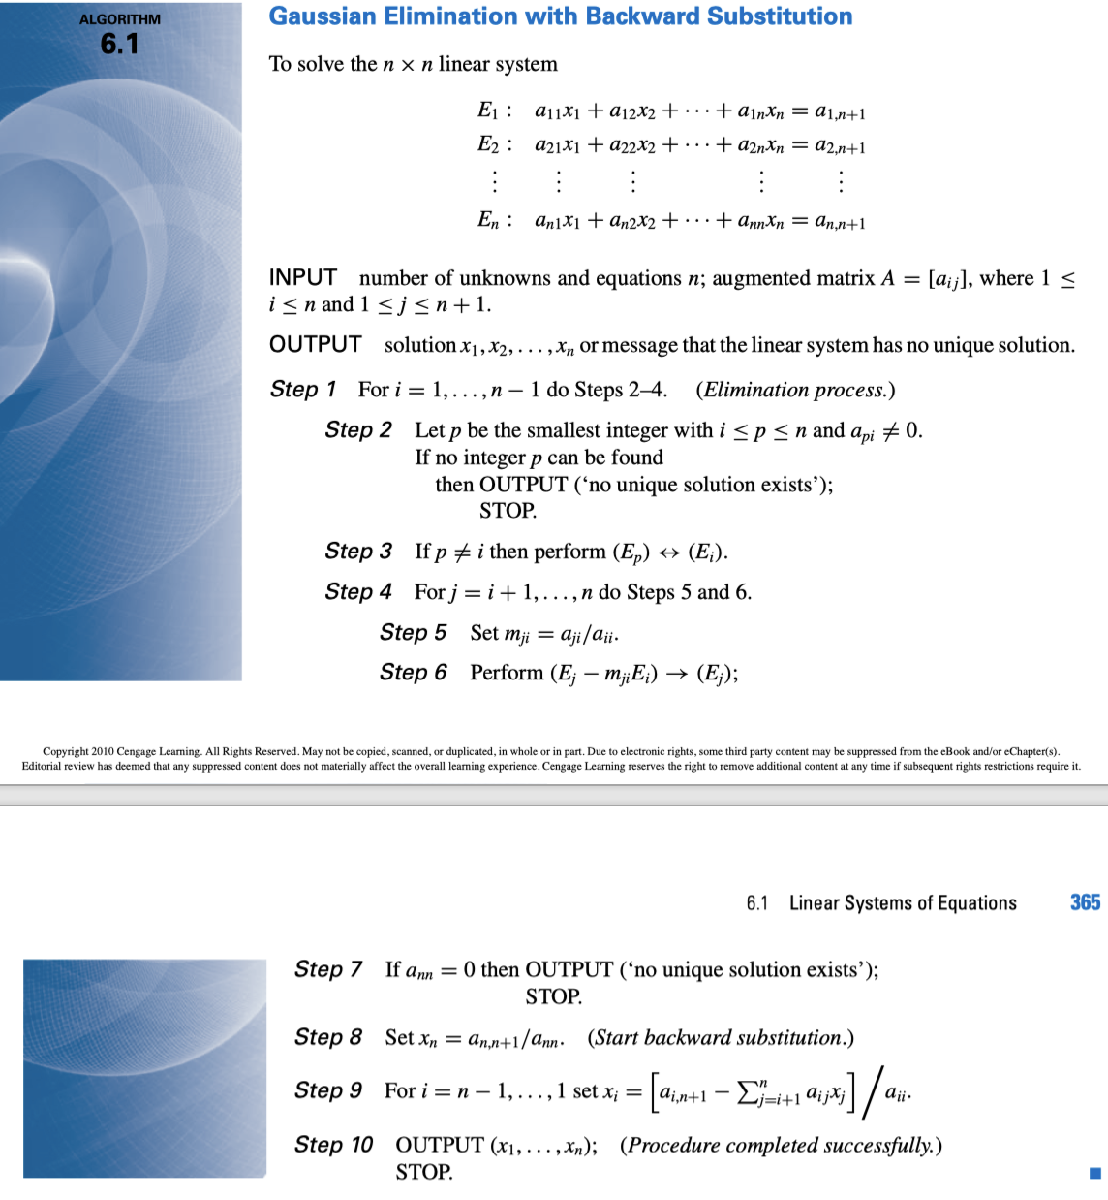

clc;clear;close all;

A=[1,-1,2,-1;
    2,-2,3,-3;
    1,1,1,0;
    1,-1,4,3];
B=[-8;
    -20;
    -2;
    4];

Ag={};                                                  %Create a cell array to store each matrix
Aau=[A,B];                                              %Generate the augmented matrix
Ag{1}=Aau;                                              %Store the first initial matrix
[n,b]=size(A);
m=[]


m =

     []



for i=1:n-1
    %Check and switch to check pivot to be not 0
    p=i;
    while Aau(p,i)==0 & p <= n-1    
        p=p+1;
    end
    if p==n & Aau(p,i)==0
        disp("No unique solution found, please check");
        break
    end
    Atemp=Aau(i,:);
    Aau(i,:)=Aau(p,:);
    Aau(p,:)=Atemp;
    for j=i+1:n
        m(j,i)=Aau(j,i)/Aau(i,i);
        Aau(j,:)=Aau(j,:)-m(j,i).*Aau(i,:);
    end
    Ag{i +1}=Aau
end

Ag = 1×2 cell 数组
    {4×5 double}    {4×5 double}


Ag = 1×3 cell 数组
    {4×5 double}    {4×5 double}    {4×5 double}


Ag = 1×4 cell 数组
    {4×5 double}    {4×5 double}    {4×5 double}    {4×5 double}



if Aau(n,n)== 0
    disp("No unique Solution Exist");
else


    % Start the backward substituition
    x=[];
    x(n)=Aau(n,n+1)/Aau(n,n);
    
    for i=n-1:-1:1
        sum=0;
        for j=i+1:n
            sum=sum+Aau(i,j)*x(j);
        end
        x(i)=(Aau(i,n+1)-sum)/Aau(i,i);
    end
    disp(x);

    -7     3     2     2



end
